# Earthquake

🌎 Analyze earthquake

## Resources

-  [https://github.com/yanndebray/matlab-with-python-book](https://github.com/yanndebray/matlab-with-python-book)

- [https://www.mathworks.com/videos/large-data-in-matlab-a-seismic-data-processing-case-study-81792.html](https://www.mathworks.com/videos/large-data-in-matlab-a-seismic-data-processing-case-study-81792.html) 

- [https://www.mathworks.com/help/matlab/matlab_prog/loma-prieta-earthquake.html](https://www.mathworks.com/help/matlab/matlab_prog/loma-prieta-earthquake.html) 

## Set up environment

setup

Defaulting to user installation because normal site-packages is not writeable

piplist

Package             Version
------------------- -------------
apparmor            3.0.4
blinker             1.4
certifi             2024.2.2
charset-normalizer  3.3.2
cryptography        3.4.8
dbus-python         1.2.18
distro              1.7.0
distro-info         1.1+ubuntu0.2
httplib2            0.20.2
idna                3.6
importlib-metadata  4.6.4
jeepney             0.7.1
keyring             23.5.0
launchpadlib        1.10.16
lazr.restfulclient  0.14.4
lazr.uri            1.0.6
LibAppArmor         3.0.4
more-itertools      8.10.0
numpy               1.26.4
oauthlib            3.2.0
pandas              2.2.1
PyGObject           3.42.1
PyJWT               2.3.0
pyparsing           2.4.7
python-apt          2.4.0+ubuntu3
python-dateutil     2.9.0.post0
pytz                2024.1
PyYAML              5.4.1
requests            2.31.0
SecretStorage       3.3.1
six                 1.16.0
systemd-python      234
tzdata              2024.1
unattended-upgrades 0.1
urllib3             2.2.

## Import data

% Python code input
pycode2 = [...
"import requests",...
"import pandas as pd",...
"",...
"# Function to fetch earthquake data from USGS API",...
"def fetch_earthquake_data(start_date, end_date):",...
"    url = f""https://earthquake.usgs.gov/fdsnws/event/1/query?format=geojson&starttime={start_date}&endtime={end_date}&minmagnitude=4""",...
"    response = requests.get(url)",...
"    data = response.json()",...
"    return data['features']",...
"",...
"# Example: Analyzing earthquake data from April 2024",...
"start_date = ""2024-04-01""",...
"end_date = ""2024-04-05""",...
"earthquake_data = fetch_earthquake_data(start_date, end_date)",...
"",...
"# Convert data to DataFrame for easier manipulation",...
"earthquake_df = pd.DataFrame(earthquake_data)",...
"",...
"# Extracting relevant information",...
"earthquake_df['magnitude'] = earthquake_df['properties'].apply(lambda x: x['mag'])",...
"earthquake_df['location'] = earthquake_df['properties'].apply(lambda x: x['place'])",...
"# earthquake_df['time'] = earthquake_df['properties'].apply(lambda x: x['time']) # Unix timestamp",...
"earthquake_df['time'] = pd.to_datetime(earthquake_df['properties'].apply(lambda x: x['time']), unit='ms') # Convert to datetime",...
"",...
"# Convert geometry to separate columns",...
"earthquake_df['longitude'] = earthquake_df['geometry'].apply(lambda x: x['coordinates'][0])",...
"earthquake_df['latitude'] = earthquake_df['geometry'].apply(lambda x: x['coordinates'][1])",...
"earthquake_df['depth'] = earthquake_df['geometry'].apply(lambda x: x['coordinates'][2])"...
];

[start_date, end_date, earthquake_data, earthquake_df] = pyrun(pycode2, ...
     [ "start_date" "end_date" "earthquake_data" "earthquake_df" ])

start_date =   Python str with no properties.

    2024-04-01


end_date =   Python str with no properties.

    2024-04-05


earthquake_data =   Python list with values:


earthquake_df =   Python DataFrame with properties:

          T: [1x1 py.pandas.core.frame.DataFrame]
         at: [1x1 py.pandas.core.indexing._AtIndexer]
      attrs: [1x1 py.dict]
       axes: [1x2 py.list]
    columns: [1x1 py.pandas.core.indexes.base.Index]
     dtypes: [1x1 py.pandas.core.series.Series]
      empty: 0
      flags: [1x1 py.pandas.core.flags.Flags]
        iat: [1x1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1x1 py.pandas.core.indexing._iLocIndexer]
      index: [1x1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1x1 py.pandas.core.indexing._LocIndexer]
       ndim: [1x1 py.int]
      shape: [1x2 py.tuple]
       size: [1x1 py.int]
     values: [1x1 py.numpy.ndarray]

            type  ...    depth
    0    Feature  ...   10.000
    1    Feature  ...   10.000
    2    Feature  ...   10.000
    3    Feature  ...   10.000
    4    Feature  ...   10.000
    ..   


% Clean up
clear pycode2;

T = table(earthquake_df);
T = removevars(T,{'type','geometry','properties'})

T = 117x7 table
         id         magnitude                 location                          time            longitude    latitude    depth 
    ____________    _________    ___________________________________    ____________________    _________    ________    ______

    "us7000m9zx"       5.1       "central Mid-Atlantic Ridge"           04-Apr-2024 23:46:41     -38.147      7.9214         10
    "us7000m9zu"         5       "central Mid-Atlantic Ridge"           04-Apr-2024 23:43:54     -38.123      7.8883         10
    "us7000m9zr"       5.2       "central Mid-Atlantic Ridge"           04-Apr-2024 23:37:29     -38.152      7.9378         10
    "us7000m9zn"         5       "central Mid-Atlantic Ridge"           04-Apr-2024 23:18:24     -38.219 

head(T)

         id         magnitude               location                       time            longitude    latitude    depth 
    ____________    _________    ______________________________    ____________________    _________    ________    ______

    "us7000m9zx"       5.1       "central Mid-Atlantic Ridge"      04-Apr-2024 23:46:41     -38.147      7.9214         10
    "us7000m9zu"         5       "central Mid-Atlantic Ridge"      04-Apr-2024 23:43:54     -38.123      7.8883         10
    "us7000m9zr"       5.2       "central Mid-Atlantic Ridge"      04-Apr-2024 23:37:29     -38.152      7.9378         10
    "us7000m9zn"         5       "central Mid-Atlantic Ridge"      04-Apr-2024 23:18:24     -38.219      8.0644         10
    "us7000m9zm"       

unique(T.location)

ans = 104x1 string array
    "10 km ESE of Hualien City, Taiwan"
    "10 km SSW of Hualien City, Taiwan"
    "103 km SSW of Uyuni, Bolivia"
    "108 km N of Paciran, Indonesia"
    "11 km E of Hualien City, Taiwan"
    "11 km N of Yopal, Colombia"
    "11 km NE of Hualien City, Taiwan"
    "114 km SSE of Kuril’sk, Russia"
    "117 km NE of Kendari, Indonesia"
    "117 km WNW of Puerto, Chile"
    "12 km ESE of Chiguayante, Chile"
    "12 km S of Hualien City, Taiwan"
    "121 km NE of Kendari, Indonesia"
    "123 km SE of Antofagasta, Chile"
    "123 km SE of Lata, Solomon Islands"
    "125 km SE of Ishigaki, Japan"
    "13 km NE of Hualien City, Taiwan"
    "134 km NW of Ternate, Indonesia"
    "136 km ENE of Saipan, Northern Mariana Islands"
    "143 km ENE of Saipan, Northern Mariana Islands"
    "15 km E of Hualien City, Taiwan"
    "15 km ESE of Hualien City, Taiwan"
    "15 km WSW of Guaymango, El Salvador"
    "152 km ENE of Lospalos, Timor Leste"
    "16 km NE of Hualien City, 

filtered_data = T(T.magnitude >= 4 & T.magnitude <= 5, :);
head(filtered_data)

         id         magnitude                 location                          time            longitude    latitude    depth 
    ____________    _________    ___________________________________    ____________________    _________    ________    ______

    "us7000m9zu"         5       "central Mid-Atlantic Ridge"           04-Apr-2024 23:43:54     -38.123      7.8883         10
    "us7000m9zn"         5       "central Mid-Atlantic Ridge"           04-Apr-2024 23:18:24     -38.219      8.0644         10
    "us7000m9zm"         5       "central Mid-Atlantic Ridge"           04-Apr-2024 23:16:56     -38.089      7.9724         10
    "us7000m9z0"         5       "35 km SW of Urakawa, Japan"           04-Apr-2024 20:31:49      142.47      41.943     

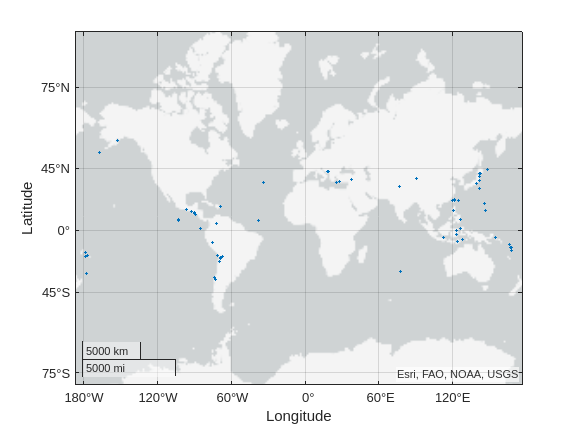

geoscatter(T.latitude,T.longitude,T.magnitude,"filled")

## Export to ipynb and md

export('livescript.mlx','README.md');
export('livescript.mlx','notebook.ipynb');